%Lab3 EMAG

%Part 1

%Given
s = 0.5:0.1:5;
epsilon_r = 10

epsilon_r = 10

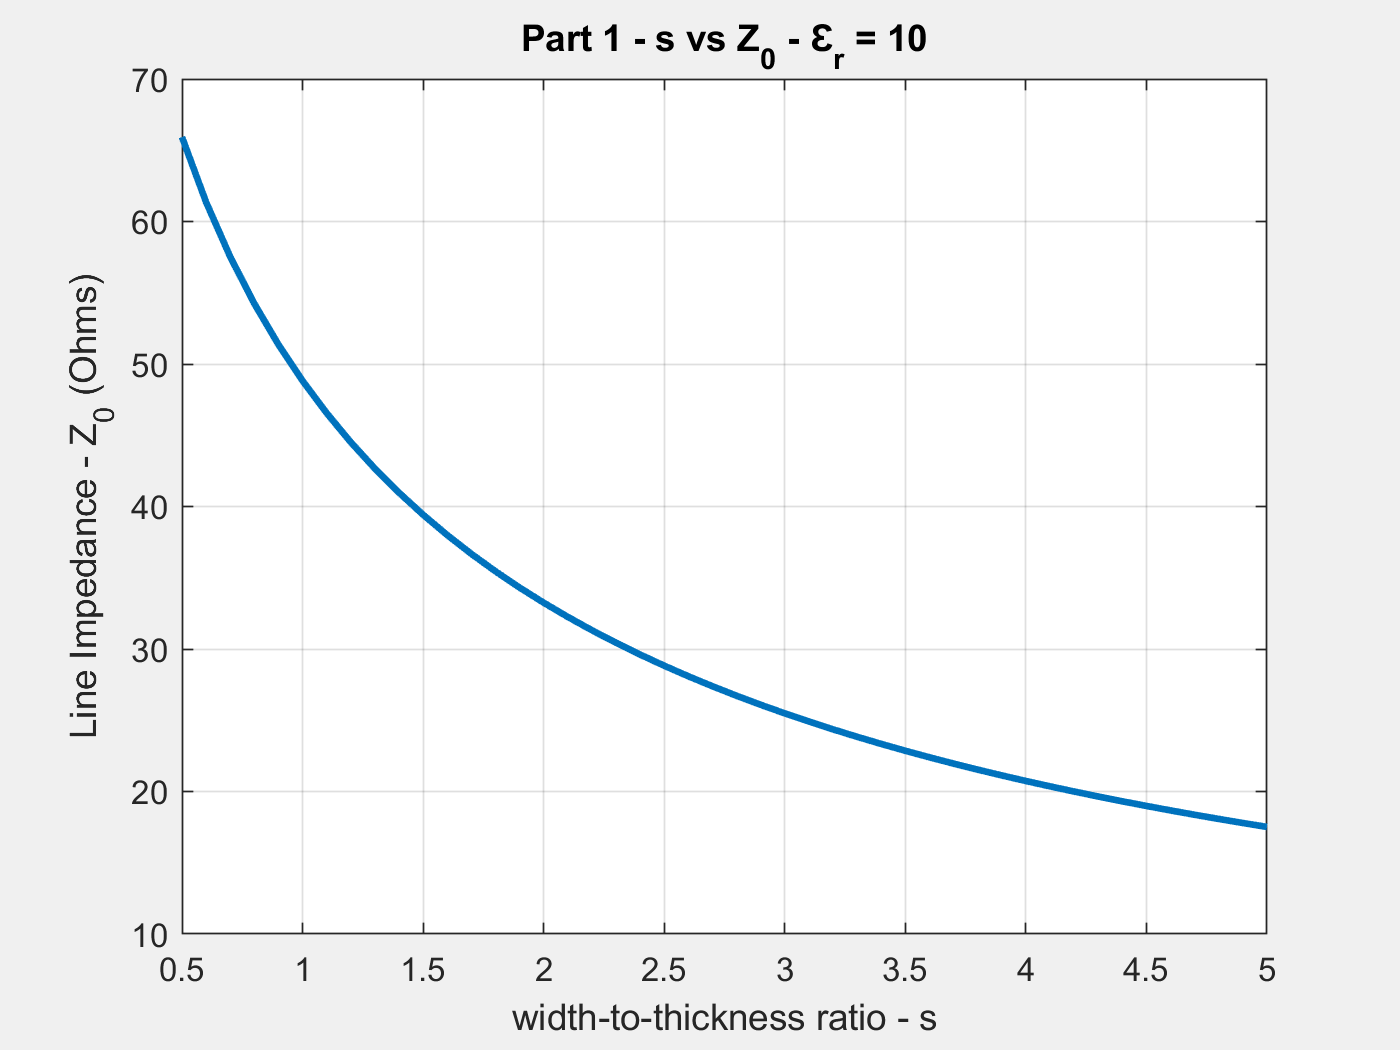


%Find

x = (epsilon_r-0.9)/(epsilon_r + 3);
x = x^0.05;
x = 0.56*x;

y = s.^4+0.00037*s.^2;
y = y./(s.^4 + 0.43);
y = 0.02*log(y);
y = y + 0.05*log(1+0.00017*s.^3);
y = y+1;

epsilon_eff = 1+10./s;
epsilon_eff = epsilon_eff.^(-x.*y);
epsilon_eff = epsilon_eff*0.5*(epsilon_r-1);
epsilon_eff = epsilon_eff + 0.5*(epsilon_r+1);

t = 30.67./s;
t = t.^0.75;

Z0 = sqrt(1+4./(s.^2));
Z0 = Z0 + (6+(2*pi-6).*exp(-t))./s;
Z0 = 60*log(Z0)./sqrt(epsilon_eff);

set(gcf, 'Visible', 'on')
plot(s, Z0, 'LineWidth', 2)
xlabel('width-to-thickness ratio - s')
ylabel('Line Impedance - Z_0 (Ohms)')
title('Part 1 - s vs Z_0 - Ɛ_r = 10')
grid on

%Part 2
sApp = [0.5 1 1.2 1.5 2 3 4 5];
Z0App = [65, 48.2, 44.2, 39.2, 33.2, 25.4, 20.7, 17.5];


%Part 3
yApp = sApp.^4+0.00037*sApp.^2;
yApp = yApp./(sApp.^4 + 0.43);
yApp = 0.02*log(yApp);
yApp = yApp + 0.05*log(1+0.00017*sApp.^3);
yApp = yApp+1;

epsilon_effApp = 1+10./sApp;
epsilon_effApp = epsilon_effApp.^(-x.*yApp);
epsilon_effApp = epsilon_effApp*0.5*(epsilon_r-1);
epsilon_effApp = epsilon_effApp + 0.5*(epsilon_r+1);

tApp = 30.67./sApp;
tApp = tApp.^0.75;

Z0AppC = sqrt(1+4./(sApp.^2));
Z0AppC = Z0AppC + (6+(2*pi-6).*exp(-tApp))./sApp;
Z0AppC = 60*log(Z0AppC)./sqrt(epsilon_effApp);

Z0Diff = (1-Z0App./Z0AppC)*100;

set(gcf, 'Visible', 'on')
subplot(2,1,1)
plot(sApp,Z0AppC,'r', 'Linewidth', 2)
hold on
plot(sApp, Z0App,'b', 'Linewidth', 2)
grid on
xlabel('width-to-thickness ratio - s')
ylabel('Line Impedance - Z_0 (Ohms)')
title('Part 3 - s vs Z_0 - Java App Comparison - Ɛ_r = 10')
legend('Calculated', 'Java App')

subplot(2,1,2)
stem(sApp, Z0Diff,'b', 'Linewidth', 2)
grid on
xlabel('width-to-thickness ratio - s')
ylabel('Relative Error (%)')

%Part 4

epsilon_r = 2;


%Find

x = (epsilon_r-0.9)/(epsilon_r + 3);
x = x^0.05;
x = 0.56*x;

y = s.^4+0.00037*s.^2;
y = y./(s.^4 + 0.43);
y = 0.02*log(y);
y = y + 0.05*log(1+0.00017*s.^3);
y = y+1;

epsilon_eff2 = 1+10./s;
epsilon_eff2 = epsilon_eff2.^(-x.*y);
epsilon_eff2 = epsilon_eff2*0.5*(epsilon_r-1);
epsilon_eff2 = epsilon_eff2 + 0.5*(epsilon_r+1);

t = 30.67./s;
t = t.^0.75;

Z04 = sqrt(1+4./(s.^2));
Z04 = Z04 + (6+(2*pi-6).*exp(-t))./s;
Z04 = 60*log(Z04)./sqrt(epsilon_eff2);

set(gcf, 'Visible', 'on')
plot(s, Z0, 'LineWidth', 2)
hold on
plot(s, Z04, 'LineWidth', 2)
xlabel('width-to-thickness ratio - s')
ylabel('Line Impedance - Z_0 (Ohms)')
title('Part 4 - s vs Z_0')
grid on
legend('Ɛ_r = 10', 'Ɛ_r = 2')

%Part 5

epsilon_r = 10

epsilon_r = 10

%Approx A

q = Z0*sqrt(epsilon_r);
q = 60*pi^2./q;

sA = log(q-1) + 0.29 - 0.52/epsilon_r;
sA = sA.*(epsilon_r-1)./(2*epsilon_r);
sA = q-1 -log(2*q-1)+sA;
sA = sA*2/pi;

%Approx B

p = 0.23 + 0.12./epsilon_r;
p = (epsilon_r-1)./(epsilon_r+1).*p;
p = sqrt(epsilon_r*0.5+0.5).*Z0/60+p;

sB = exp(2*p) - 2;
sB = 8*exp(p)./sB;


sADiff = 100*(1-sA./s);
sBDiff = 100*(1-sB./s);

xCondition = (44 - 2*epsilon_r)*ones(length(sADiff));
yCondition = linspace(0.01, max(sADiff), length(sADiff));
twoPercent = 2*ones(length(Z0));

hold off
set(gcf, 'Visible', 'on')
subplot(3,1,1)
loglog(Z0, sA, 'r', 'LineWidth', 2)
hold on
loglog(Z0, sB, 'b', 'LineWidth', 2)
loglog(Z0, s, 'k', 'LineWidth', 2)


grid on
xlabel('Line Impedance - Z_0 (Ohms)')
ylabel('width-to-thickness ratio - s')
title('Part 5 - Z_0 vs s - Ɛ_r = 10')
legend('Approximation A', 'Approximation B', 'Part 1 Calculation')

subplot(3,1,2)
plot(Z0, abs(sADiff), 'r', 'LineWidth', 2)
hold on
plot(Z0, abs(sBDiff), 'b', 'LineWidth', 2)
plot(xCondition, yCondition, 'g-', 'LineWidth', 2)
plot(Z0, twoPercent, 'c-', 'LineWidth', 2)
grid on
xlabel('Line Impedance - Z_0 (Ohms)')
ylabel('Relative Error (%)')
legend('Approximation A', 'Approximation B', 'Z_0 = 44 - 2Ɛ_r', 'Location', 'best')

subplot(3,1,3)
loglog(Z0, abs(sADiff), 'r', 'LineWidth', 2)
hold on
loglog(Z0, abs(sBDiff), 'b', 'LineWidth', 2)
loglog(xCondition, yCondition, 'g-', 'LineWidth', 2)
loglog(Z0, twoPercent, 'c-', 'LineWidth', 2)
grid on
xlabel('Line Impedance - Z_0 (Ohms)')
ylabel('Relative Error (%)')
legend('Approximation A', 'Approximation B', 'Z_0 = 44 - 2Ɛ_r', 'Location', 'best')



epsilon_r = 2;

%Approx A

q = Z04*sqrt(epsilon_r);
q = 60*pi^2./q;

sA = log(q-1) + 0.29 - 0.52/epsilon_r;
sA = sA.*(epsilon_r-1)./(2*epsilon_r);
sA = q-1 -log(2*q-1)+sA;
sA = sA*2/pi;

%Approx B

p = 0.23 + 0.12./epsilon_r;
p = (epsilon_r-1)./(epsilon_r+1).*p;
p = sqrt(epsilon_r*0.5+0.5).*Z04/60+p;

sB = exp(2*p) - 2;
sB = 8*exp(p)./sB;

sADiff = 100*(1-sA./s);
sBDiff = 100*(1-sB./s);

xCondition = (44 - 2*epsilon_r)*ones(length(sADiff));
yCondition = linspace(0.01, max(sADiff), length(sADiff));
twoPercent = 2*ones(length(Z04));

hold off
set(gcf, 'Visible', 'on')
subplot(3,1,1)
loglog(Z04, sA, 'r', 'LineWidth', 2)
hold on
loglog(Z04, sB, 'b', 'LineWidth', 2)
loglog(Z04, s, 'k', 'LineWidth', 2)


grid on
xlabel('Line Impedance - Z_0 (Ohms)')
ylabel('width-to-thickness ratio - s')
title('Part 5 - Z_0 vs s - Ɛ_r = 2')
legend('Approximation A', 'Approximation B', 'Part 1 Calculation')

subplot(3,1,2)
plot(Z04, abs(sADiff), 'r', 'LineWidth', 2)
hold on
plot(Z04, abs(sBDiff), 'b', 'LineWidth', 2)
plot(xCondition, yCondition, 'g-', 'LineWidth', 2)
plot(Z04, twoPercent, 'c-', 'LineWidth', 2)
grid on
xlabel('Line Impedance - Z_0 (Ohms)')
ylabel('Relative Error (%)')
legend('Approximation A', 'Approximation B', 'Z_0 = 44 - 2Ɛ_r', 'Location', 'best')

subplot(3,1,3)
loglog(Z04, abs(sADiff), 'r', 'LineWidth', 2)
hold on
loglog(Z04, abs(sBDiff), 'b', 'LineWidth', 2)
loglog(xCondition, yCondition, 'g-', 'LineWidth', 2)
loglog(Z04, twoPercent, 'c-', 'LineWidth', 2)
grid on
xlabel('Line Impedance - Z_0 (Ohms)')
ylabel('Relative Error (%)')
legend('Approximation A', 'Approximation B', 'Z_0 = 44 - 2Ɛ_r', 'Location', 'best')




